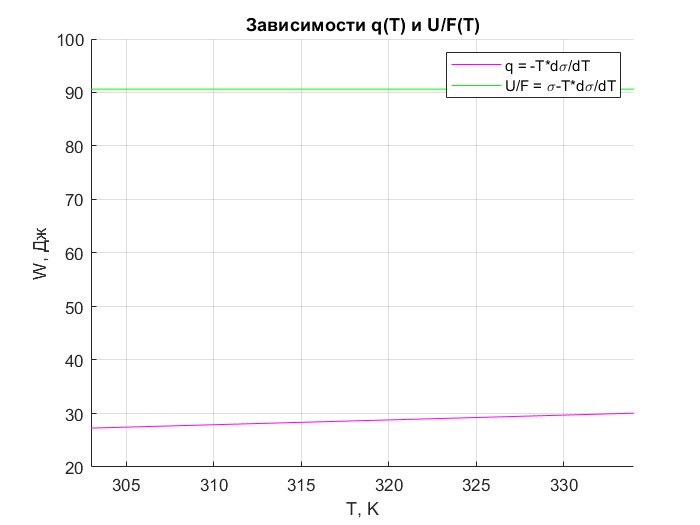

 
hold on
grid on
T = [30.1 35 40 45 50 55 60] + 273;
sigma = [63.08 63.17 62.48 62.06 61.63 61.03 60.60];
y_1 = 0.09*(T);
y_2 = sigma+0.09*(T);
xlim([303,334])
xi = min(301):0.1:max(334);
N = 1; % степень
coeff1 = polyfit(T, y_1, N);
y1 = 0;
for k=0:N
    y1 = y1 + coeff1(N-k+1) * xi.^k;
end
gr1 = plot(xi, y1, 'm'); 

xi = min(301):0.1:max(334);
N = 1; % степень
coeff2 = polyfit(T, y_2, N);
y2 = 0;
for k=0:N
    y2 = y2 + coeff2(N-k+1) * xi.^k;
end
gr2 = plot(xi, y2, 'g');
title("Зависимости q(T) и U/F(T)")
xlabel('T, K')
ylabel('W, Дж')
legend("q = -T*d\sigma/dT",'U/F = \sigma-T*d\sigma/dT')
hold off